## ***第一题***

### ***a. 通过Z-Y-X欧拉角计算旋转矩阵***

自定义函数rotationx，得到绕x轴旋转的旋转矩阵

自定义函数输出的结果：

clc, clear;
rotationx(pi/3)

ans =     1.0000         0         0
         0    0.5000   -0.8660
         0    0.8660    0.5000


使用Robotics工具箱中的函数输出的结果：

rotx(pi/3)

ans =     1.0000         0         0
         0    0.5000   -0.8660
         0    0.8660    0.5000


自定义函数rotationy，得到绕y轴旋转的旋转矩阵

自定义函数输出的结果：

rotationy(pi/3)

ans =     0.5000         0    0.8660
         0    1.0000         0
   -0.8660         0    0.5000


使用Robotics工具箱中的函数输出的结果：

roty(pi/3)

ans =     0.5000         0    0.8660
         0    1.0000         0
   -0.8660         0    0.5000


自定义函数rotationz，得到绕z轴旋转的旋转矩阵

自定义函数输出的结果：

rotationz(pi/3)

ans =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


使用Robotics工具箱中的函数输出的结果：

rotz(pi/3)

ans =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


自定义函数eulerzyx2rotm，通过输入的Z-Y-X欧拉角，计算出旋转矩阵

验算1：$\alpha=10^{\circ}, \beta=20^{\circ}, \gamma=30^{\circ}
$

自定义函数输出的结果：

eulerzyx2rotm(10, 20, 30, 'deg')

ans =     0.9254    0.0180    0.3785
    0.1632    0.8826   -0.4410
   -0.3420    0.4698    0.8138


使用Robotics工具箱中的函数输出的结果：

rotz(10, 'deg') * roty(20, 'deg') * rotx(30, 'deg')

ans =     0.9254    0.0180    0.3785
    0.1632    0.8826   -0.4410
   -0.3420    0.4698    0.8138


验算2：$\alpha=10^{\circ}, \beta=20^{\circ}, \gamma=30^{\circ}
$

自定义函数输出的结果：

eulerzyx2rotm(30, 90, -55, 'deg')

ans =          0   -0.9962    0.0872
         0    0.0872    0.9962
   -1.0000         0         0


使用Robotics工具箱中的函数输出的结果：

rotz(30, 'deg') * roty(90, 'deg') * rotx(-55, 'deg')

ans =          0   -0.9962    0.0872
         0    0.0872    0.9962
   -1.0000         0         0


#### ***证明单位正交旋转矩阵的6个约束条件***

由上面的计算过程可以看出，欲得到一个3×3的旋转矩阵，实际上只需要输入3个参数（例如上面的3个欧拉角），这说明矩阵中只有3个参数是独立的。

#### 证明$^B_AR = ^A_BR^{-1} = ^A_BR^T$

R = eulerzyx2rotm(30, 90, -55, 'deg')

R =          0   -0.9962    0.0872
         0    0.0872    0.9962
   -1.0000         0         0


R_inv = inv(R)

R_inv =          0         0   -1.0000
   -0.9962    0.0872         0
    0.0872    0.9962         0


R_T = R'

R_T =          0         0   -1.0000
   -0.9962    0.0872         0
    0.0872    0.9962         0


由上面的计算可以看出，$^B_AR = ^A_BR^{-1} = ^A_BR^T$是成立的。

### ***b. 通过旋转矩阵得到欧拉角***

自定义函数eulerzyx2rotm，可以根据旋转矩阵，计算出Z-Y-X欧拉角

R1 = eulerzyx2rotm(10, 20, 30, 'deg');
eul1 = rotm2eulerzyx(R) * 180/pi

eul1 =      0    90   -85


R2 = eulerzyx2rotm(30, 90, -55, 'deg');
eul2 = rotm2eulerzyx(R2) * 180/pi

eul2 =      0    90   -85


注意到第二个例子中输入的欧拉角和输出的欧拉角不完全相同，这是因为$\beta = 90^{\circ}
$使得旋转矩阵出现奇异，在这种情况下一般取$\alpha = 0^{\circ}
$，因此最终算得的欧拉角和最初输入的欧拉角不完全相同，但是它们所表示的变换的效果是一样的。

### ***c. 仅简单地绕y轴旋转***

Ry = rotationy(20, 'deg')

Ry =     0.9397         0    0.3420
         0    1.0000         0
   -0.3420         0    0.9397


BP = [1; 0; 1]

BP =      1
     0
     1


AP = Ry * BP

AP =     1.2817
         0
    0.5977


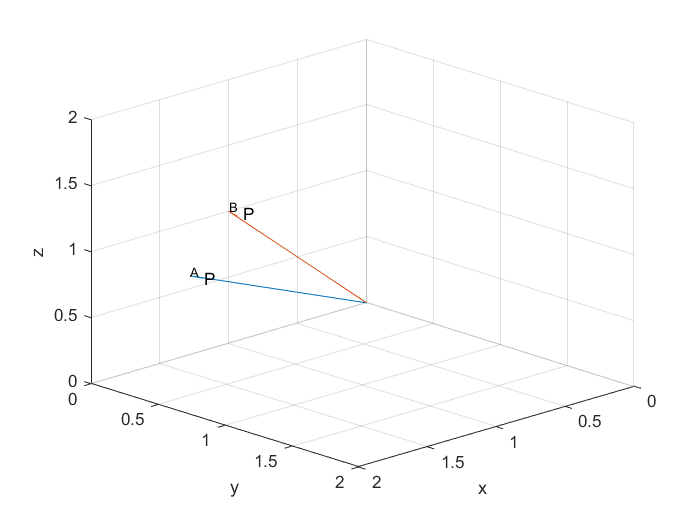

f1 = figure;
scale=1;
quiver3(0,0,0, AP(1),AP(2),AP(3),scale);
text(AP(1),AP(2),AP(3),'^A P');
hold on;
quiver3(0,0,0, BP(1),BP(2),BP(3),scale);
text(BP(1),BP(2),BP(3),'^B P');
hold on;
grid on;%绘网格
xlabel('x');ylabel('y');zlabel('z');
axis([0 2 0 2 0 2]);
view([135.86 23.75])

从图中可以看出，$^A P
$与$^B P
$夹角约为20度（此时将旋转矩阵视作变换算子）

## ***第二题***

### ***a. 计算齐次变换矩阵***

第一个例子：


$$\alpha = 10^{\circ} , \beta = 20^{\circ} , \gamma = 30^{\circ}  , ^AP_B = \{ 1, 2, 3\}^T$$


自定义函数输出结果如下：

translation(1,2,3) * trotationz(10, 'deg') * trotationy(20,'deg') * trotationx(30,'deg')

ans =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


工具箱中函数输出结果如下：

transl(1,2,3) * trotz(10, 'deg') * troty(20,'deg') * trotx(30, 'deg')

ans =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


第二个例子：


$$\alpha = 0^{\circ} , \beta = 20^{\circ} , \gamma = 0^{\circ}  , ^AP_B = \{ 3, 0, 1\}^T$$


自定义函数输出结果如下：

translation(3,0,1) * trotationz(0, 'deg') * trotationy(20,'deg') * trotationx(0,'deg')

ans =     0.9397         0    0.3420    3.0000
         0    1.0000         0         0
   -0.3420         0    0.9397    1.0000
         0         0         0    1.0000


工具箱中函数输出结果如下：

transl(3,0,1) * trotz(0, 'deg') * troty(20,'deg') * trotx(0, 'deg')

ans =     0.9397         0    0.3420    3.0000
         0    1.0000         0         0
   -0.3420         0    0.9397    1.0000
         0         0         0    1.0000


### ***b. 坐标变换***

已知$\alpha = 0^{\circ} , \beta = 20^{\circ} , \gamma = 0^{\circ}  , ^AP_B = \{ 3, 0, 1\}^T$以及$^B P = \{1, 0, 1\}$可以按照如下计算出$^A P$

APB = [3;0;1];
T = translation(3,0,1) * trotationz(0, 'deg') * trotationy(20,'deg') * trotationx(0,'deg');
BP = [1;0;1];
AP = T*([BP;1]);
AP = AP(1:3)

AP =     4.2817
         0
    1.5977


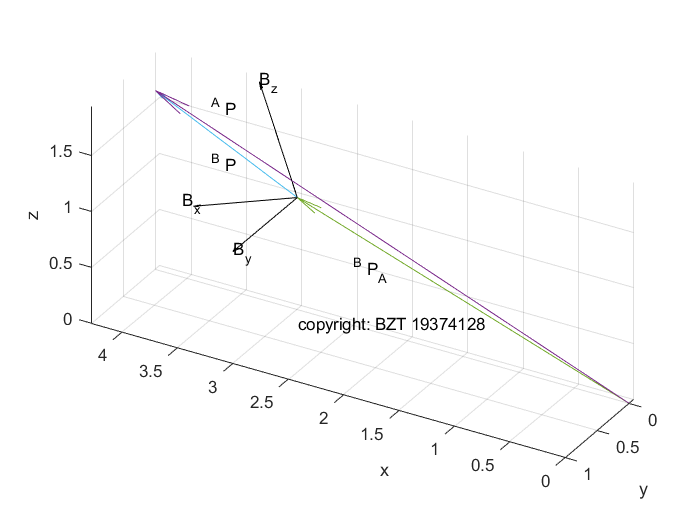

AoriginB = APB;
Bx = T(1:3, 1); By = T(1:3, 2); Bz = T(1:3, 3);
f2 = figure;
scale=1;
quiver3(APB(1),APB(2), APB(3), Bx(1),Bx(2),Bx(3),scale, 'filled','black');
text(APB(1)+Bx(1)+0.1,APB(2)+Bx(2),APB(3)+Bx(3),'B_x');
hold on;
quiver3(APB(1),APB(2), APB(3), By(1),By(2),By(3),scale, 'filled','black');
text(APB(1)+By(1),APB(2)+By(2),APB(3)+By(3),'B_y');
hold on;
quiver3(APB(1),APB(2), APB(3), Bz(1),Bz(2),Bz(3),scale, 'filled','black');
text(APB(1)+Bz(1),APB(2)+Bz(2),APB(3)+Bz(3),'B_z');
hold on;
quiver3(0,0,0, AP(1),AP(2),AP(3),scale);
text(AP(1)-0.5,AP(2),AP(3),'^A P');
hold on;
quiver3(0,0,0, APB(1),APB(2), APB(3),scale);
text(APB(1)-0.5,APB(2),APB(3)-0.5,'^B P_A');
hold on;
quiver3(APB(1),APB(2), APB(3), AP(1)-APB(1),AP(2)-APB(2),AP(3)-APB(3),scale);
text(AP(1)-0.5,AP(2),AP(3)-0.5,'^B P');
text(2.7, 0.5, 0.2, "copyright: BZT 19374128")
hold on;
grid on;%绘网格
xlabel('x');ylabel('y');zlabel('z');
axis equal;
view([-149.82 29.19])

题目中要求利用数值验证齐次变换矩阵的三种描述，我将这些数值体现在了上面这个图像中，并逐一解释：

- 它是位姿的描述：在上图中，通过齐次变换矩阵画出了坐标轴{B}，可以看出，坐标轴{A}经过平移和旋转得到了坐标轴{B}，这和齐次变换矩阵中蕴含的信息是相同的。

- 它是变换映射：如上图所示，齐次变换矩阵可以将$^B P$（蓝色箭头）映射为$^A P$（紫色箭头）

- 它是变换算子：上图也可以理解为，将蓝色箭头对应的向量旋转再平移后得到了紫色箭头对应的向量

### ***c. 利用符号运算，计算齐次变换矩阵的逆矩阵***

我的MATLAB中没有symbolic math toolbox，无法进行符号运算

因此对于此题，我使用了mathematica软件进行解决

具体程序见文件”齐次变换逆矩阵.nb“，可以通过Wolfram Mathemtica或者Wolfram Player将其打开运行

或者打开“齐次变换逆矩阵.pdf”文件查看

### ***d. 齐次变换矩阵的运算***

i) 利用变换图说明关系

ABT = transl(1,2,3) * trotz(10, 'deg') * troty(20,'deg') * trotx(30, 'deg');
BCT = transl(3,0,1) * trotz(0, 'deg') * troty(20,'deg') * trotx(0, 'deg');
ACT = ABT*BCT;
Bx = ABT(1:3, 1); By = ABT(1:3, 2); Bz = ABT(1:3, 3);
Cx = ACT(1:3, 1); Cy = ACT(1:3, 2); Cz = ACT(1:3, 3);
Bo = ABT(1:3, 4);
Co = ACT(1:3, 4);Co = double(Co);

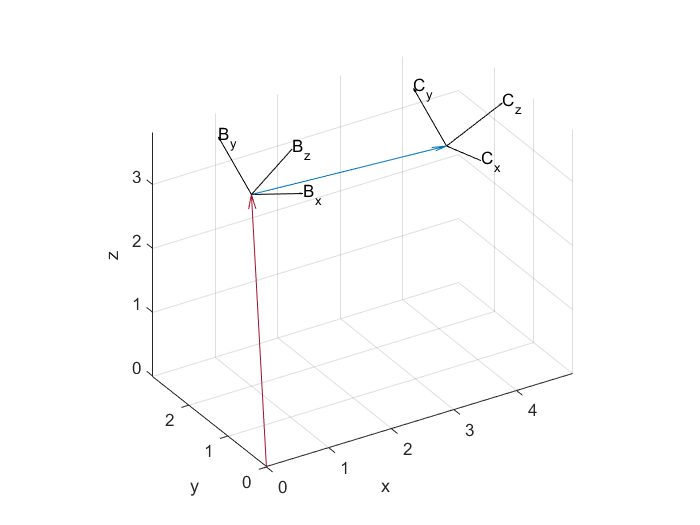

f3 = figure;
scale=1;
quiver3(Bo(1),Bo(2),Bo(3),Bx(1),Bx(2),Bx(3),scale, 'filled','black');
text(Bo(1)+Bx(1), Bo(2)+Bx(2), Bo(3)+Bx(3), "B_x");
hold on;
quiver3(Bo(1),Bo(2),Bo(3),By(1),By(2),By(3),scale, 'filled','black');
text(Bo(1)+By(1), Bo(2)+By(2), Bo(3)+By(3), "B_y");
hold on;
quiver3(Bo(1),Bo(2),Bo(3),Bz(1),Bz(2),Bz(3),scale, 'filled','black');
text(Bo(1)+Bz(1), Bo(2)+Bz(2), Bo(3)+Bz(3), "B_z");
hold on;

quiver3( Co(1), Co(2), Co(3), Cx(1), Cx(2), Cx(3), scale, 'filled','black');
text(Co(1)+Cx(1), Co(2)+Cx(2), Co(3)+Cx(3), "C_x");
hold on;
quiver3(Co(1),Co(2),Co(3),Cy(1),Cy(2),Cy(3),scale, 'filled','black');
text(Co(1)+Cy(1), Co(2)+Cy(2), Co(3)+Cy(3), "C_y");
hold on;
quiver3(Co(1),Co(2),Co(3),Cz(1),Cz(2),Cz(3),scale, 'filled','black');
text(Co(1)+Cz(1), Co(2)+Cz(2), Co(3)+Cz(3), "C_z");
hold on;

quiver3(0,0,0, Bo(1), Bo(2), Bo(3), scale);
hold on;
quiver3(Bo(1), Bo(2), Bo(3), Co(1)-Bo(1), Co(2)-Bo(2), Co(3)-Bo(3), scale);

grid on;%绘网格
xlabel('x');ylabel('y');zlabel('z');
axis equal;

view([-31.80 29.72])

ii) 利用$^A_CT, ^B_CT$求解$^A_BT$

ACT * (inv(BCT))

ans =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


ABT

ABT =     0.9254    0.0180    0.3785    1.0000
    0.1632    0.8826   -0.4410    2.0000
   -0.3420    0.4698    0.8138    3.0000
         0         0         0    1.0000


可以看到利用$^A_CT, ^B_CT$求解$^A_BT$和原来的$^A_BT$相同

iii) 利用$^A_CT, ^A_BT$求解$^B_CT$

inv(ABT) * ACT

ans =     0.9397   -0.0000    0.3420    3.0000
   -0.0000    1.0000    0.0000    0.0000
   -0.3420    0.0000    0.9397    1.0000
         0         0         0    1.0000


BCT

BCT =     0.9397         0    0.3420    3.0000
         0    1.0000         0         0
   -0.3420         0    0.9397    1.0000
         0         0         0    1.0000


可以看到，利用$^A_CT, ^A_BT$求解$^B_CT$和原来的$^B_CT$相同